# ASE-4046 Exercise 7 Solutions

## Problem 1

### ***Part a***

Frequency table made "by hand":

`  bin         #`

`  [600,700)   1`

`  [700,800)   2`

`  [800,900)   4`

`  [900,1000)  9`

`  [1000,1100) 4  `

`  all        20`

Check it with Matlab:

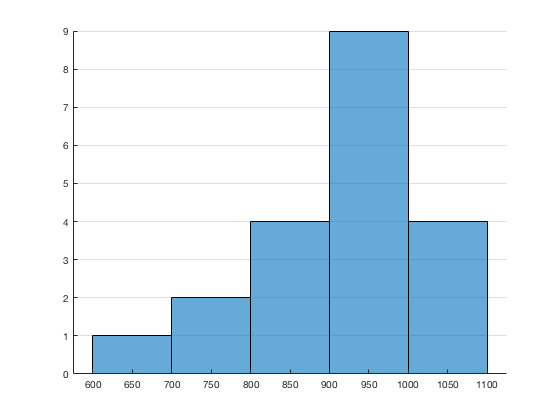

x1879=[850 900 930 950 980 1000 930 760 1000 960 ...
       740 1070 850 980 880 980 650 810 1000 960];
edges=600:100:1100;
histogram(x1879,edges)
set(gca,'box','off','ygrid','on')

### Part b

Make the histogram with default bin edges:

histogram(x1879)
set(gca,'box','off','ygrid','on')

The bin edges are the same as in the part 1. The histogram shows that the distribution is unimodal and slightly skewed left (i.e. the left tail is longer).  

### Part c

Empirical cumulative distribution function

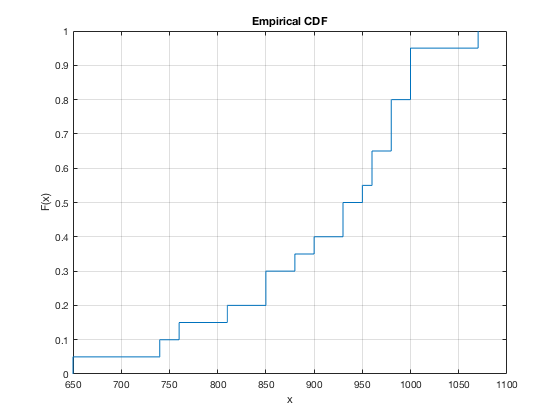

cdfplot(x1879)

The ECDF is equal to 0.5 on the interval [930,950). This is the "mathematical" median, i.e. the 0.5 quartile.

The ECDF crosses 0.25 at 850 and and 0.75 at 980; these are the first and third quartiles.

### Part d

The quartiles as computed by Matlab are

q=quantile(x1879,[0.25 0.5 0.75])

q =    850   940   980


 The inlier range is 

[q(1) q(3)]+[-1.5,1.5]*iqr(x1879)

ans =          655        1175


There is one outlier, the point 650. 

### Part e

Box plots:

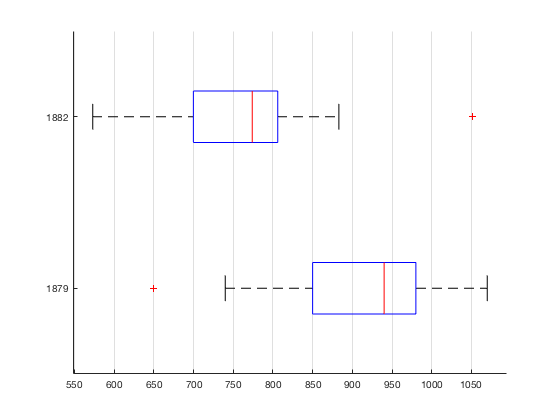

x1882=[883 778 682 611 1051 578 774 772 573 748 851 723 ...
       816 796 711 599 781 796 820 696 748 797 809];
x=[x1879 x1882];  % concatenate data into a single vector
Batch=[1879*ones(size(x1879)) 1882*ones(size(x1882)) ]; % batch labels
boxplot(x,Batch,'orientation','horizontal')
set(gca,'box','off','xgrid','on')

The box plots indicate that both data sets are slightly left-skewed (the medians are off-centre in the IQR region). 

The 1882 data values are smaller: the values differ so much that the IQR regions are clearly separated. 

The 1882 data has a bit less spread:

iqr(x1879), iqr(x1882)

ans = 130

ans = 106.2500

## Problem 2

First, produce the plot using default parameters. 

a=[4 4 4 4]; b=[2 4 8 16];
x=0:.01:1;
clear p
for k=1:length(a)
    p(k,:)=betapdf(x,a(k),b(k));
end
h=plot(x,p);   % save the figure handle

Adjust parameters using commands. Editing can also be done with the interactive Matlab figure editor, but a script is easier to modify and reuse.

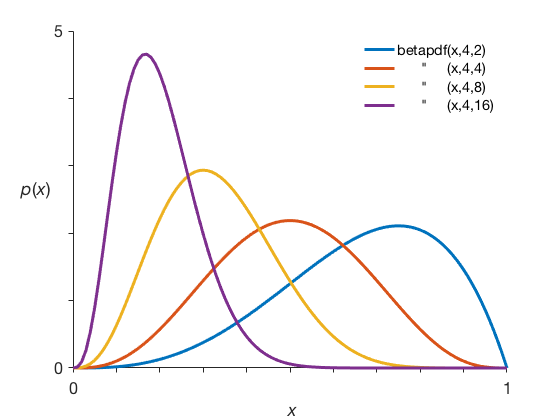

set(gca,'box','off',...      % remove the box (unnecessary ink)
     'fontsize',16,  ...     % increase font size for readability
     'tickdir','out', ...    % axis tick marks shouldn't collide with data 
     'xtick',0:.1:1, ...     % a denser tick spacing improves lookup possibility 
     'xticklabel',{'0','','','','','','','','','','1'}, ...  % remove unnecessary tick labels
     'ytick',0:5,'yticklabel',{'0','','','','','5'})         % ditto for y ticks and their labels
set(h,'linewidth',3)             % thicker curves
xlabel('\it x','fontsize',20)    % label the x-axis (italic)
ylabel(' {\itp}({\itx})','fontsize',20, ...                  % label the y-axis
        'rot',0,'horizontalAlignment','right')               % rotate it to read left-to-right
legend('betapdf(x,4,2)', ...       % legend labels the curves
     '      "     (x,4,4)', ...    % avoid unnecessary repetition
     '      "     (x,4,8)', ...
     '      "     (x,4,16)',...    
       'box','off')                % remove the box (unnecessary ink)  